%Test Single File
%fileLocation = workingFiles(image).folder + "/" + workingFiles(image).name;
fileLocation = "./workingImages/starfish_noise7.jpg"

fileLocation = "./workingImages/starfish_noise7.jpg"

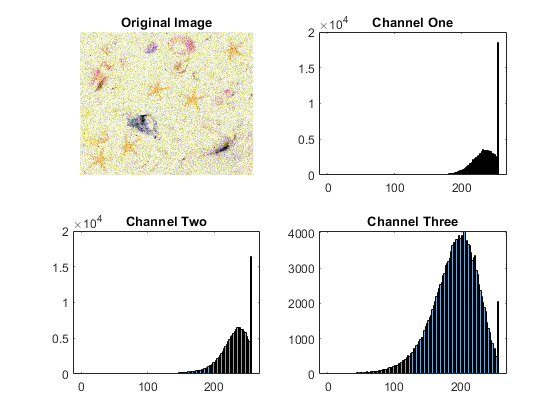

red Channel salt and pepper noise


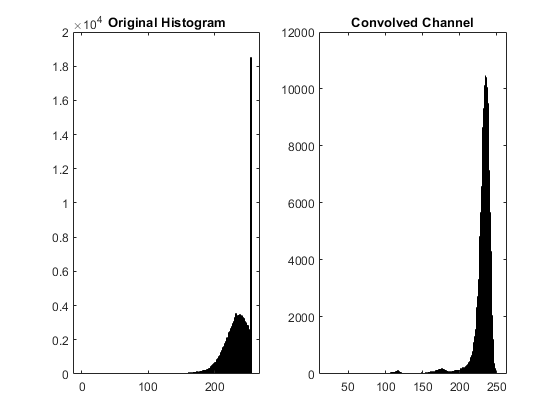

Green Channel Salt and Pepper Noise


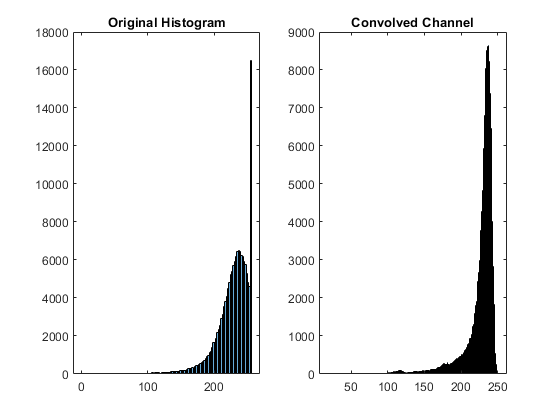

Blue Channel Salt and Pepper Noise


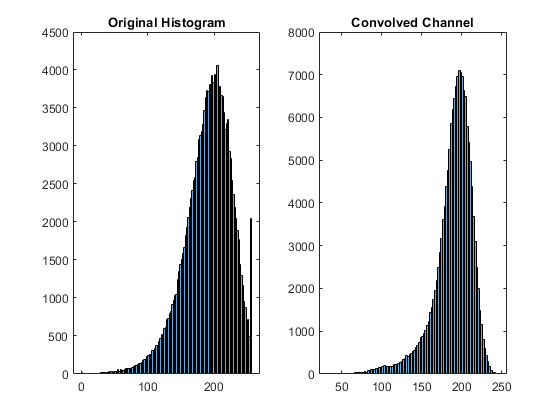

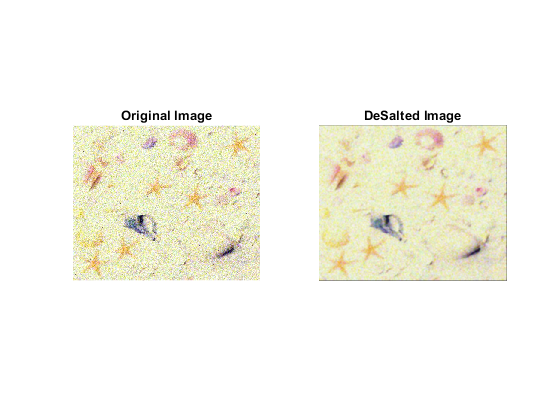

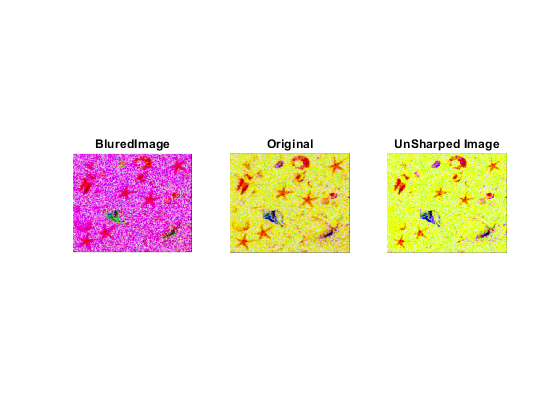

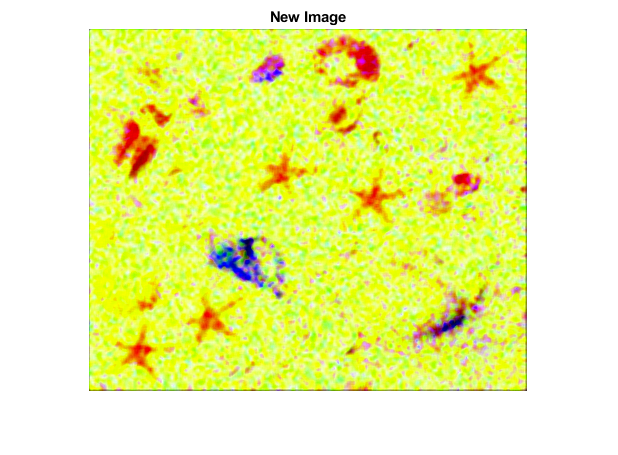

Taking Blue Channel
Getting the complement


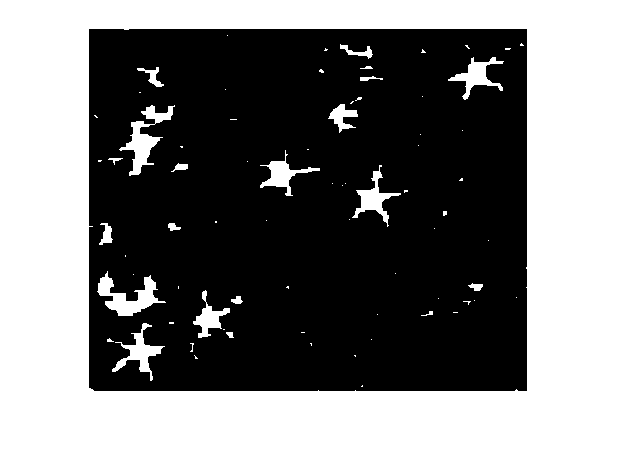

[mask, original] = pipeline1(fileLocation);

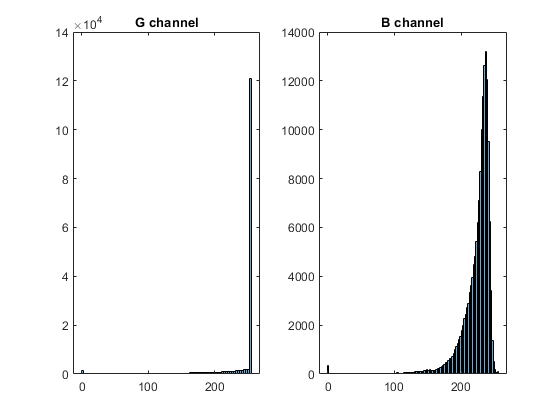

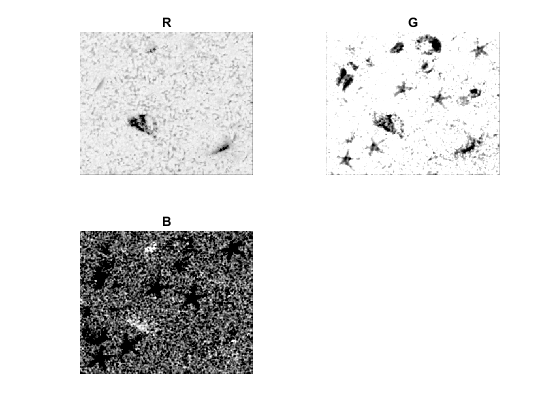

%texAnalysis(mask, original);
bw =  mask - bwareaopen(mask,2500);
figure
imshow(bw);

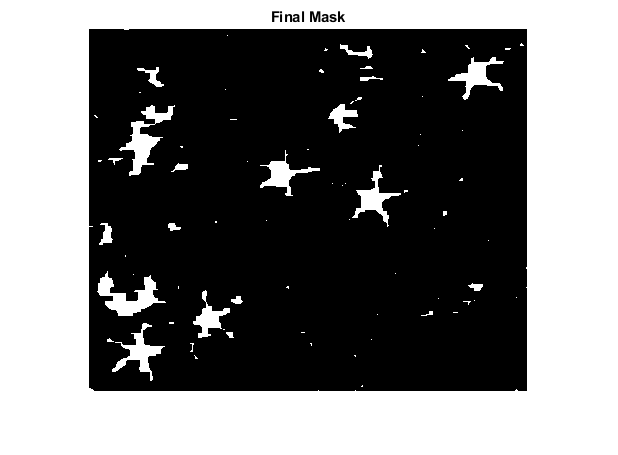

title("Final Mask");

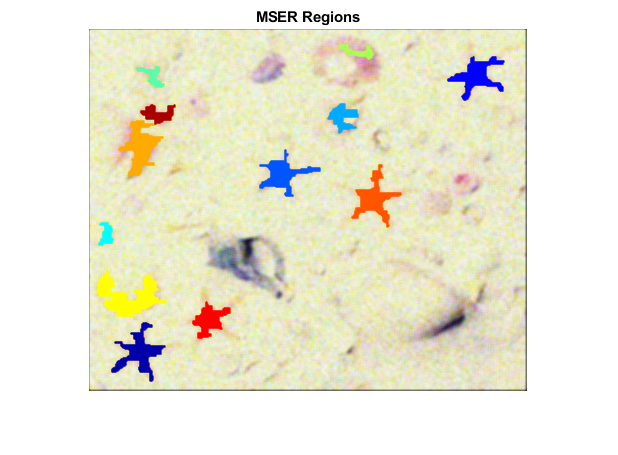

1: BoudningBox:  X: 8.5 Y: 242.5 Eccentricity: 0.81858 Solidity: 0.5371 Area: 1216
2: BoudningBox:  X: 359.5 Y: 28.5 Eccentricity: 0.70739 Solidity: 0.44602 Area: 785
3: BoudningBox:  X: 263.5 Y: 136.5 Eccentricity: 0.62946 Solidity: 0.40411 Area: 786
4: BoudningBox:  X: 171.5 Y: 121.5 Eccentricity: 0.71971 Solidity: 0.40803 Area: 732
5: BoudningBox:  X: 104.5 Y: 273.5 Eccentricity: 0.73126 Solidity: 0.63105 Area: 561
6: BoudningBox:  X: 48.5 Y: 38.5 Eccentricity: 0.86032 Solidity: 0.55352 Area: 181
7: BoudningBox:  X: 30.5 Y: 92.5 Eccentricity: 0.84033 Solidity: 0.54075 Area: 909
8: BoudningBox:  X: 23.5 Y: 294.5 Eccentricity: 0.56155 Solidity: 0.39671 Area: 845


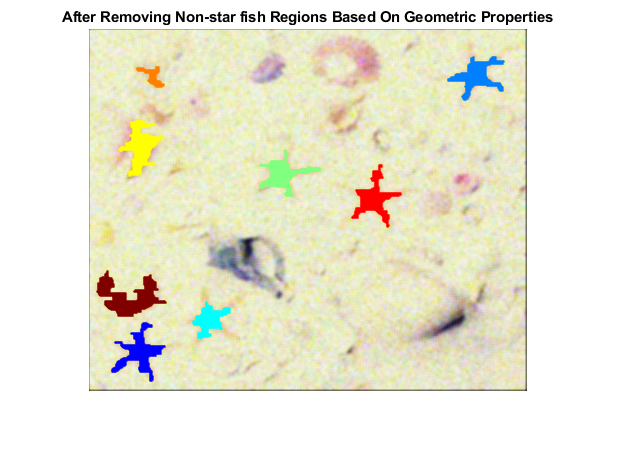

[fullStat, boundingBoxes, NoStarfish] = MSERRegionAnalysis(bw, original);

sizeOfBoudingBox = size(boundingBoxes);
output = figure;
imshow(original);
hold on;
for x = 1:sizeOfBoudingBox(1)
    
  thisBB = boundingBoxes(x, (1:4));
  text(thisBB(1) + thisBB(3) /2, thisBB(2) - 10,"" + x);
  rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],'EdgeColor','r','LineWidth', 2);
    

end
hold off;
title("Final Output: There are " + NoStarfish + " Starfish");
mkdir("./" + NoStarfish + "/");

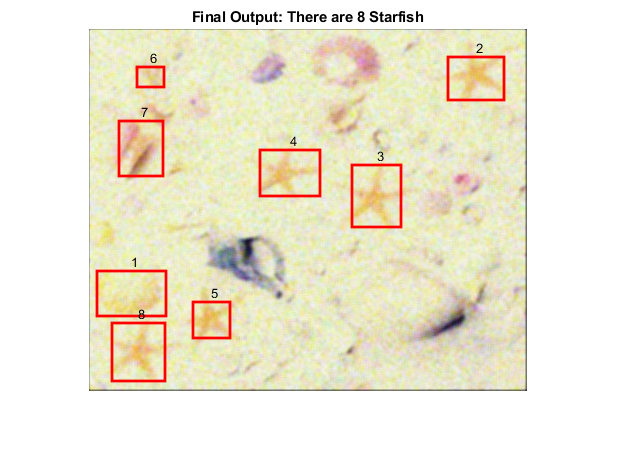

saveas(output, "./" + NoStarfish + "/" + workingFiles(image).name);